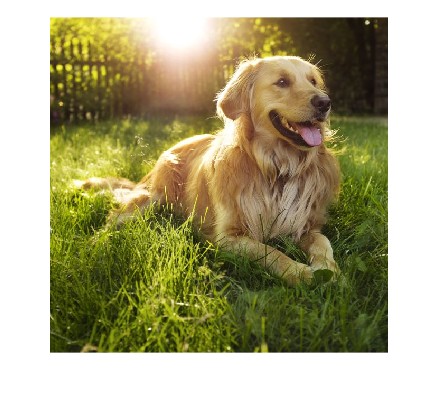

img = imread("img.jpg");
imshow(img);

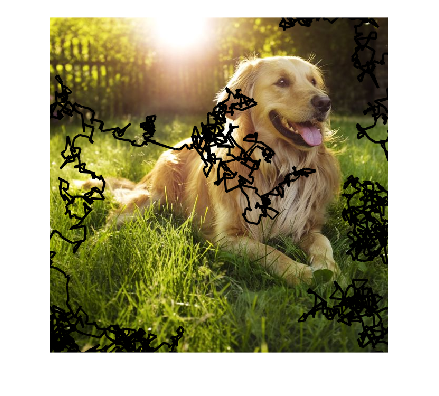


I = img;
vec = [size(img,1)/2,size(img,2)/2];
lns = vec;

for k = 1 : randi([1000,10000])
    
    vec = vec + normrnd(0,10,1,2);
    lns(k,3:4) = vec;
    lns(k+1,1:2) = vec;
    
end
lns(k+1,3:4) = vec;

I = insertShape(I,'line',lns,'LineWidth',5,"Color","black","SmoothEdges",true);

imshow(I)